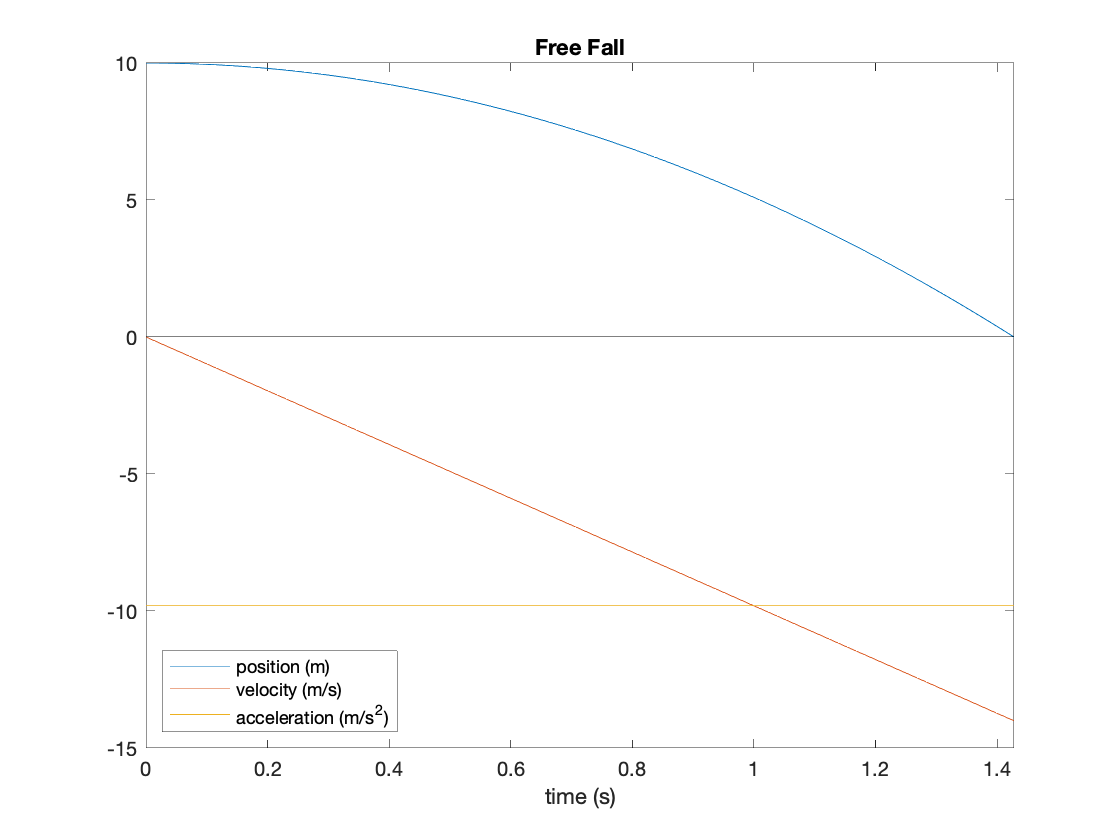

% Trajectory of free-falling body.
g = 9.81;   % (m/s^2)
h = 10;     % (m)
v0 = 0;     % (m/s)
% Time to reach the ground
T = v0/g + sqrt((v0/g)^2 + 2*h/g);
t = linspace(0,T,100);
x = @(u) h + v0*u - g*u.^2/2;
v = @(u) v0 - g*u;
a = @(u) repmat(-g, size(u));
hp = plot(t, [x(t); v(t); a(t)]);
xlim([0 T])
line(xlim,[0 0],'Color','k')
legend(hp, 'position (m)', 'velocity (m/s)', 'acceleration (m/s^2)','location','southwest')
title('Free Fall')
xlabel('time (s)')